Recreating the molecular-clutch model from fig. 1 of this paper: https://www.science.org/doi/10.1126/science.1163595

% Recreated this model using the code we got from the paper writers as a
% reference... still need to comment + clean this up more - Brandon

clear all

% Model Parameters (extracted from Table S1 in SI)
% ====================================================
%                  [Unit]   Variable definition
% ====================================================
n_m = 75;          %          Number of myosin motors
F_m = -2;          % [pN]     Single myosin motor stall force
v_u = -120;        % [nm/s]   Unloaded myosin motor velocity
n_c = 75;          %          Number of molecular clutches
k_on = 1;          % [s^(-1)] Rate of clutch binding
k_off = 0.1;       % [s^(-1)] Rate of clutch unbinding
F_b = -2;      % [pN]     Characteristic bond rupture force
k_clutch = 5;      % [pN/nm]  Molecular clutch spring constant

function [is_bind, state_idx, dt] = simulate_next_event(clutch_states, F_clutch, k_on, F_b, k_off)
    % Gillepsie algorithm implementation
    unengaged_clutch_indices = find(clutch_states==0);
    engaged_clutch_indices = find(clutch_states==1);

    if isempty(unengaged_clutch_indices)
        t_bind=inf;
    else
        t_bind=-log(rand(1, length(unengaged_clutch_indices)))/k_on;
    end

    if isempty(engaged_clutch_indices)
        t_unbind=inf;
    else
        t_unbind=-log(rand(1, length(engaged_clutch_indices)))./(k_off * exp(F_clutch(engaged_clutch_indices) / F_b));
    end

    [min_t_unbind, unbind_idx] = min(t_unbind);
    [min_t_bind, bind_idx] = min(t_bind);
    
    if min_t_bind < min_t_unbind
        % Binding event happens first
        is_bind = 1;
        state_idx = unengaged_clutch_indices(bind_idx);
        dt = min_t_bind;
    else
        % Unbinding event happens first
        is_bind = 0;
        state_idx = engaged_clutch_indices(unbind_idx);
        dt = min_t_unbind;
    end
end

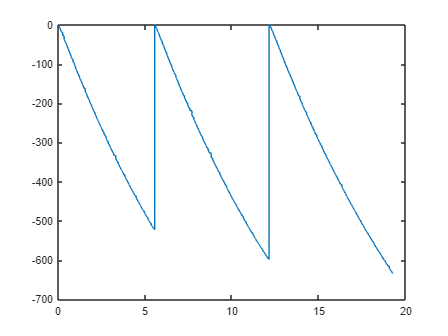

% Running Variables
% =======================
x_clutches = zeros(1, n_c);
clutch_states = zeros(1, n_c);
x_substrate = 0;
t = 0;
events_simulated = 2000;
x_substrates_t = zeros(1, events_simulated);
t_points = zeros(1, events_simulated);
k_substrate = 0.1;

for i = 1:events_simulated
    % Calculate velocity of the F-actin
    v_filament = v_u * (1 - ((k_substrate * x_substrate) / (n_m * F_m)));

    % Calculate force on the clutches
    F_clutch = k_clutch * (x_clutches - x_substrate);
    
    % Use Gillepsie algorithm to simulate the next event
    [is_bind, state_idx, dt] = simulate_next_event(clutch_states, F_clutch, k_on, F_b, k_off);
    
    % Change the state of the clutch
    clutch_states(state_idx) = is_bind;
    if ~is_bind
        x_clutches(state_idx) = x_substrate;
    end
    
    engaged_clutch_idx = find(clutch_states==1);
    disengaged_clutch_idx = find(clutch_states==0);
    
    % Find the position of the substrate
    x_substrate = (k_clutch * sum(x_clutches(engaged_clutch_idx))) / (k_substrate + (length(engaged_clutch_idx) * k_clutch));
    
    % Displace engaged clutches
    x_clutches(engaged_clutch_idx) = x_clutches(engaged_clutch_idx) + (v_filament * dt);
    
    % Set disengaged clutch displacement to the displacement of the
    % substrate
    x_clutches(disengaged_clutch_idx) = x_substrate;
    t = t + dt;

    x_substrates_t(i) = x_substrate;
    t_points(i) = t;
end

plot(t_points, x_substrates_t, '-');

% Running Variables
% =======================
x_clutches = zeros(1, n_c);
clutch_states = zeros(1, n_c);
x_substrate = 0;
t = 0;
events_simulated = 1e5;
v_filaments_t = zeros(1, events_simulated);
dts = zeros(1, events_simulated);
k_substrates = logspace(-1, 2, 10); % [pN/nm]  Substrate spring constant
average_vs = zeros(1, length(k_substrates));

tic
i = 1;
for k_substrate = k_substrates
    for ii = 1:events_simulated
        % Calculate velocity of the F-actin
        v_filament = v_u * (1 - ((k_substrate * x_substrate) / (n_m * F_m)));

        % Calculate force on the clutches
        F_clutch = k_clutch * (x_clutches - x_substrate);
        
        % Use Gillepsie algorithm to simulate the next event
        [is_bind, state_idx, dt] = simulate_next_event(clutch_states, F_clutch, k_on, F_b, k_off);
        
        % Change the state of the clutch
        clutch_states(state_idx) = is_bind;
        if ~is_bind
            x_clutches(state_idx) = x_substrate;
        end
        
        engaged_clutch_idx = find(clutch_states==1);
        disengaged_clutch_idx = find(clutch_states==0);
        
        % Find the position of the substrate
        x_substrate = (k_clutch * sum(x_clutches(engaged_clutch_idx))) / (k_substrates(i) + (length(engaged_clutch_idx) * k_clutch));
        
        % Displace engaged clutches
        x_clutches(engaged_clutch_idx) = x_clutches(engaged_clutch_idx) + (v_filament * dt);
        
        % Set disengaged clutch displacement to the displacement of the
        % substrate
        x_clutches(disengaged_clutch_idx) = x_substrate;
        t = t + dt;

        % if x_substrate == 0
        %     clutch_states = zeros(1, n_c);
        % end
    
        v_filaments_t(ii) = v_filament;
        dts(ii) = dt;
    end
    average_vs(i) = sum(v_filaments_t .* dts) / sum(dts);
    i = i + 1;
end
toc

Elapsed time is 12.482741 seconds.


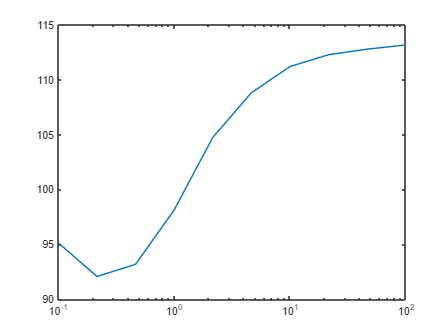


semilogx(k_substrates, -average_vs, '-');